# Lysosome Stats

Use this script to generate the figures presented in the manuscript. 

Requires the following variables to be loaded:

## Load Variables

Change directory to the Lysosome Analysis Folder 

clearvars -except paths proj
close all
clc
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths)
idT = sortrows(idT,["Type", "Health"])

### Group Stats by cell

Calculate the stats of the lysosomes per cells. 

s = groupsummary(lysT,"Cell",["sum","median","mean","std","max","min"],"Volume");
s.Properties.VariableNames = {'Cell',...
    'LysCount', 'LysTotalVol','LysMedianVol','LysMeanVol','LysStdVol','LysMaxVol','LysMinVol'}

s.Cell = replace(s.Cell,"TB2_TCdying-01_cw","TB2_TCdying01"); % reconstruction includes "bits"
s.Cell = replace(s.Cell,"TB2_TCdying-02_cw","TB2_TCdying02");

- **LysCount**: total number of lysosomes found in a cell

- **LysTotalVolume**: summed volume of all lysosomes found in a cell

- **LysMedianVol**: median volume of lysosomes found in a cell

- **LysTraceMedian**: The median cross-sectional area of a lysosome in a given cell

### Add percent volume

Percent volume is total lysosome volume divided by cell volume


$$\textrm{LysCellRatio}=\frac{\textrm{Total}\;\textrm{Lysosome}\;\textrm{Volume}\;}{\textrm{Cell}\;\textrm{Volume}}$$


cellT = join(cellT,s);
% cellT = sortrows(cellT,"Object");
cellT.LysCellRatio = cellT.LysTotalVol./ cellT.Volume

- I and III healthy cells are about the same size

- I dying cell is larger than the other two cells

## Visualization

### Plot: Lysosome Count and Median Lysosome Volume

likely a function of volume

figure(Visible="on",WindowStyle="docked",Color='white')

tiledlayout("horizontal")

% la = true(height(cellT),1);
% la = ~contains(cellT.Object,'AP37');
g = cellT.PlotSort;
y = cellT.LysCount;

y2 = cellT.LysMedianVol;
y2_label = ("Median Lys Vol")

y2_label = "Median Lys Vol"

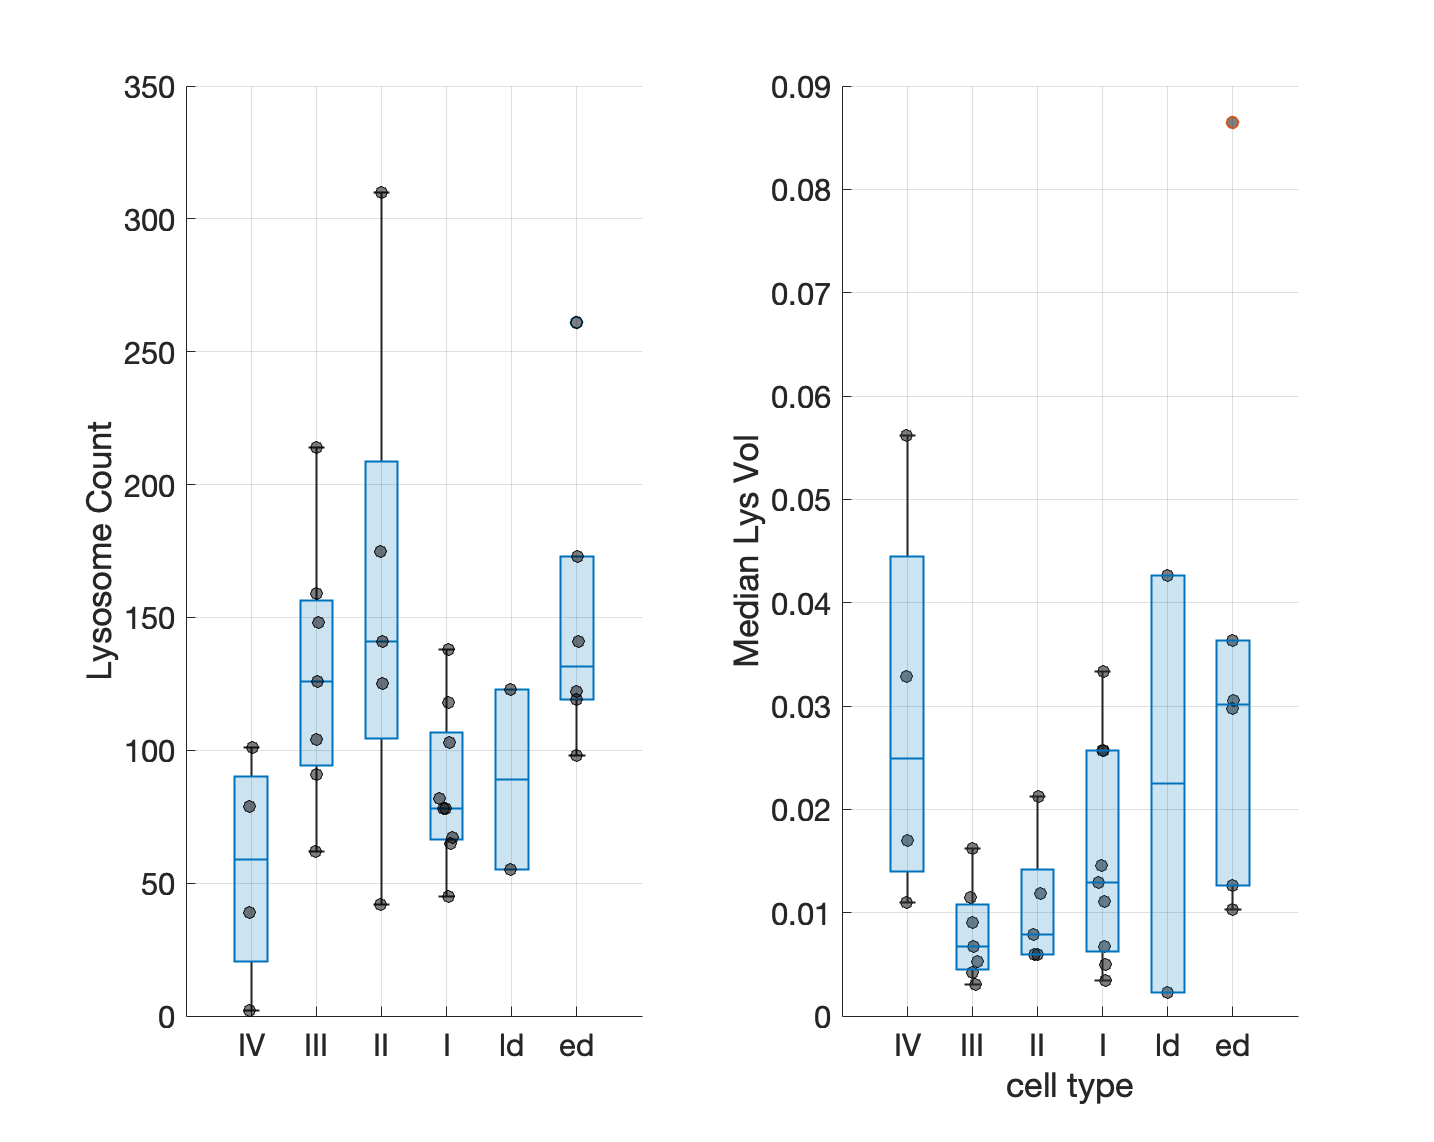


% y2 = cellT.LysCellRatio;

nexttile
hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
% boxchart(g,y,GroupByColor=g,Notch="off")


ylabel("Lysosome Count")
xlabel("")
grid on


nexttile

swarmchart(g,y2, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
hold on
boxchart(g,y2,"BoxFaceColor","#0072BD",Notch="off")

xlabel("cell type")
grid on

ylabel(y2_label)

## Volume Analysis

### Cell stats

cell_stats = groupsummary(cellT,"PlotSort",["min" "max"],"Volume")
disp(cell_stats)

    PlotSort    GroupCount    min_Volume    max_Volume
    ________    __________    __________    __________

      IV            4           191.43         742.6  
      III           7           524.77        810.45  
      II            5           810.93        1173.7  
      I             9           394.35          1634  
      ld            2            403.6        457.08  
      ed            6           536.17        1984.4  



## Visualize

### Total Lysosome Volume per cell

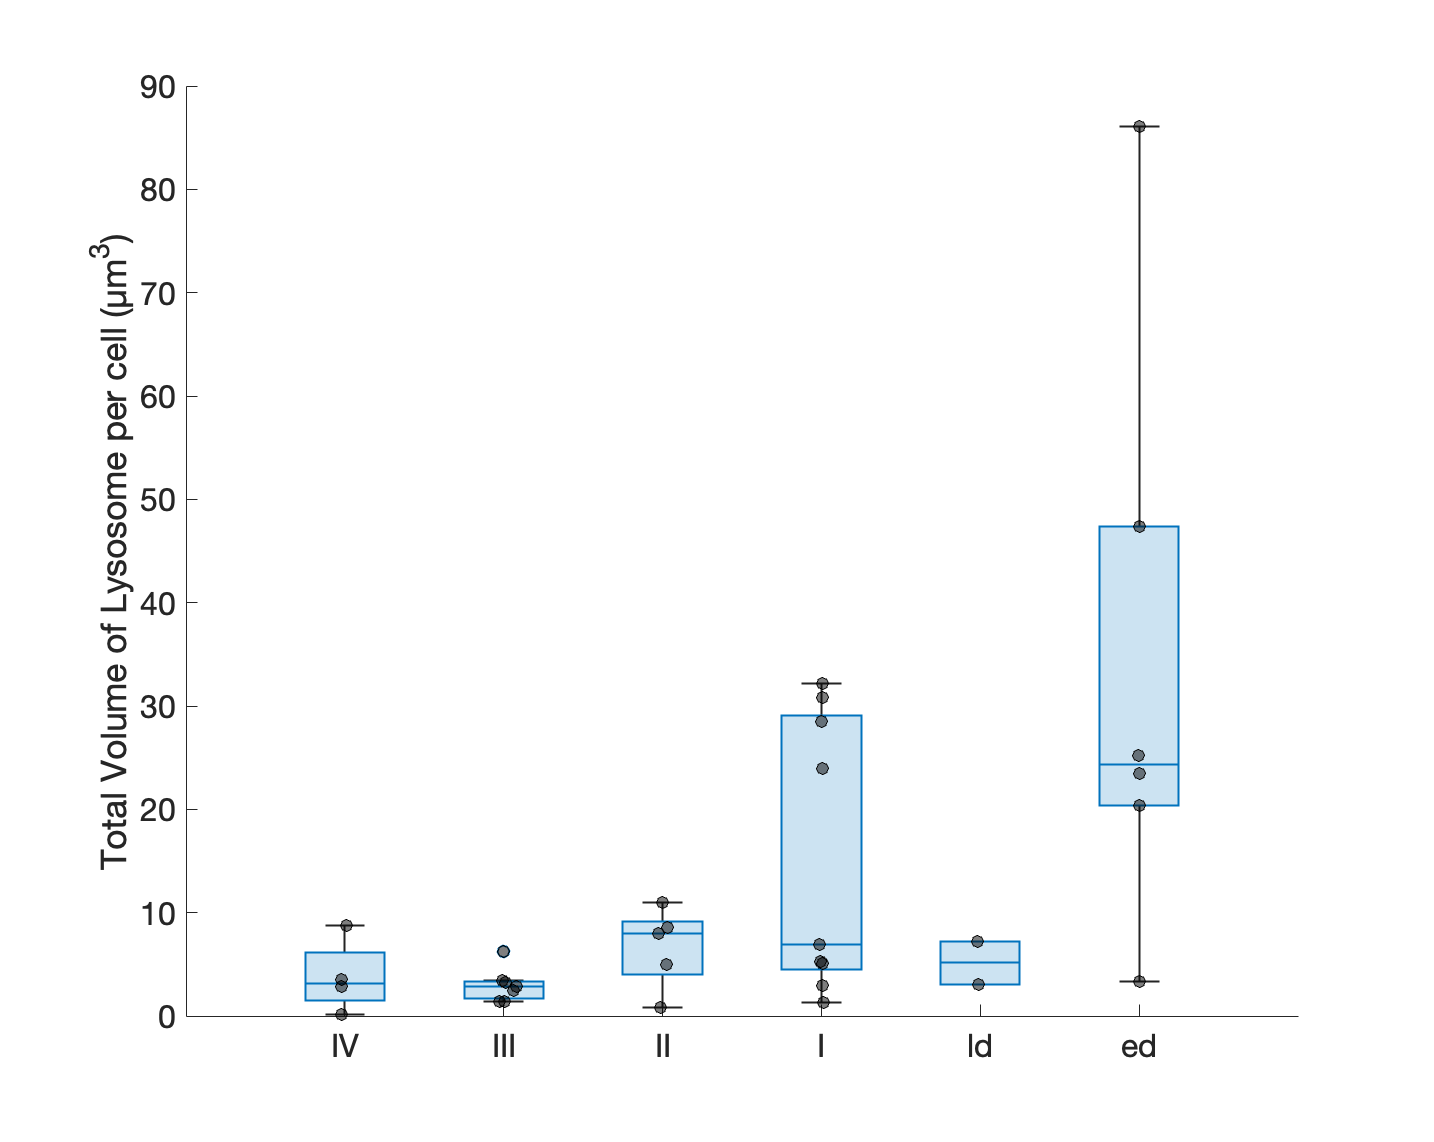

mmfig;

tiledlayout("horizontal")

g = cellT.PlotSort;
y = cellT.LysTotalVol;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Total Volume of Lysosome per cell (µm^3)")

### Ratio: Lysosome Total Volume to Cell Volume

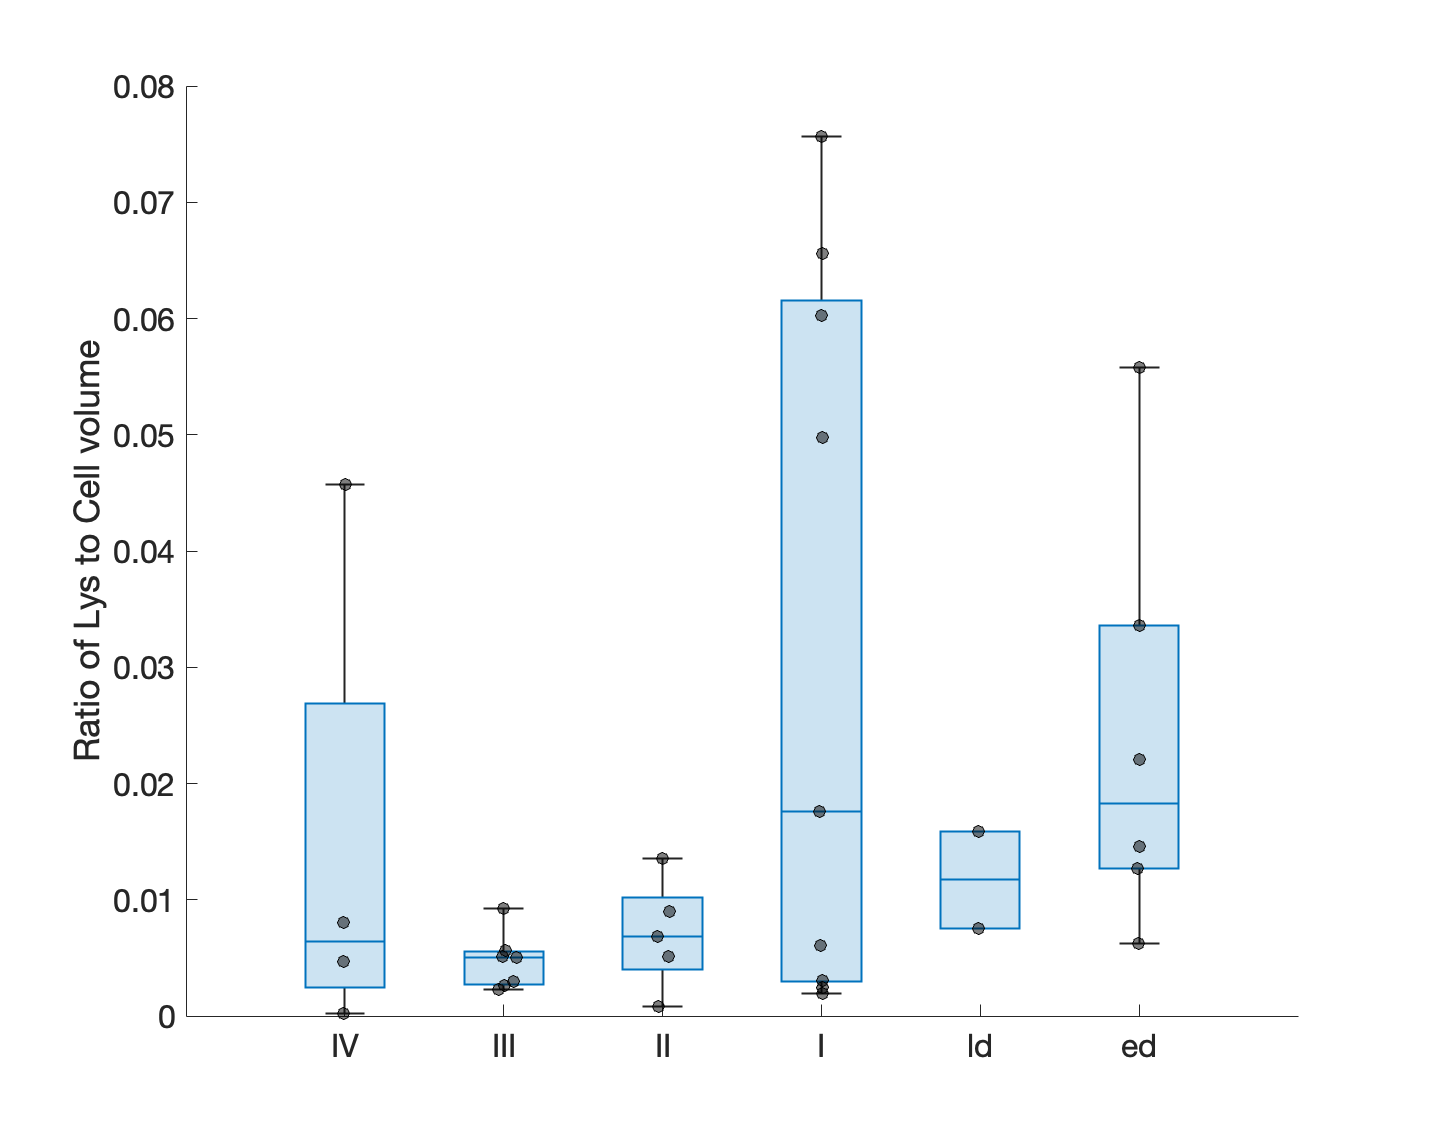

mmfig;
tiledlayout("horizontal")

g = cellT.PlotSort;
y = cellT.LysCellRatio;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel("Ratio of Lys to Cell volume")